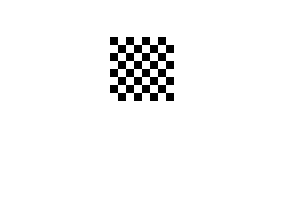

img = zeros(64);
for i=0:7
    for j=0:7        
        img(8*i+1:8*(i+1),8*j+1:8*(j+1))=mod(i+j,2);     
    end
end
figure(1);
imshow(img);

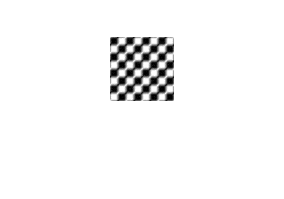

LEN=5;
Theta=45;
PSF=fspecial('motion',LEN,Theta);
MF=imfilter(img,PSF,'circular','conv');
noise=imnoise(zeros(64),'gaussian',0,0.001);

%imshow(MF);
MFN=MF+noise;
figure(2);
imshow(MFN);

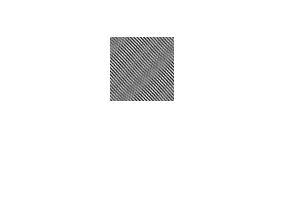



%逆滤波
figure(3);
imshow(deconvwnr(MFN,PSF),[]);

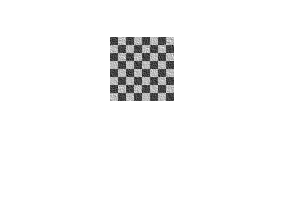


%维纳滤波
NSR=sum(noise(:).^2/sum(MFN(:).^2));
figure(4);
imshow(deconvwnr(MFN,PSF,NSR),[]);

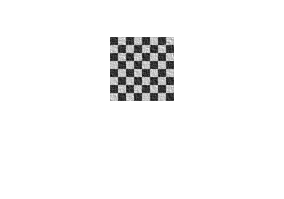


%最小二乘方滤波
figure(5);
imshow(deconvreg(MFN,PSF,0.4,[1e-7 1e7]),[]);